%%MATLAB Machine Learning Script for Homework 10

%Split the data into numfolds equal-sized segments. 
numfolds = 5;
%Dimensions to try for PCA dimensionality reduction.
kvalues = [10 25 50 100 250 500]; 
numkvalues = length(kvalues);

%Initialize arrays to store error rate estimates.
train_error_NN  = zeros(numfolds,length(kvalues));
test_error_NN = zeros(numfolds,length(kvalues));
train_error_LDA = zeros(numfolds,length(kvalues));
test_error_LDA = zeros(numfolds,length(kvalues));
train_error_QDA = zeros(numfolds,length(kvalues));
test_error_QDA = zeros(numfolds,length(kvalues));

%Read in cats/dogs dataset.
[dataset0, dataset1] = read_cats_dogs;
%To slightly speed up the script, load the cats and dogs dataset once, then
%comment out the line above while running the rest as you refine your code.
%Don't forget to uncomment the read_cats_dogs line if you close and reopen
%Matlab.

%Determine size of datasets.
[n0 d0] = size(dataset0);
[n1 d1] = size(dataset1);
n = n0 + n1;
if (d0 == d1)
    d = d0;
else
    error("dataset0 and dataset1 have a different number of columns.")
end

%Create data matrix and label vector.
datamatrix = [dataset0;dataset1];
labelvector = [zeros(n0,1);ones(n1,1)];

%Randomly permute dataset As a result, the probability of error
%will change with each run of the whole script.
permutation = randperm(n);

%Loop over folds, using the mth fold for testing, remainder for
%training.
for m = 1:numfolds
    disp(sprintf('Fold %g out of %g.',m,numfolds));
    permshift = circshift(permutation,floor(n*m/numfolds));
    dataperm = datamatrix(permshift,:);
    labelperm = labelvector(permshift,:);
    %Split dataset into training and test data.
    Xtrain = dataperm(1:floor(n*(numfolds-1)/numfolds),:);
    Xtest = dataperm(floor(n*(numfolds-1)/numfolds)+1:n,:);
    Ytrain = labelperm(1:floor(n*(numfolds-1)/numfolds),:);
    Ytest = labelperm(floor(n*(numfolds-1)/numfolds)+1:n,:);
    ntrain = size(Xtrain,1);
    ntest = size(Xtest,1);

    %Estimate mean vector and covariance matrix from Xtrain.
    mu = mean(Xtrain);
    sigma = cov(Xtrain);
    %Determine eigenvalues and eigenvectors. 
    [V D] = eig(sigma);
    
    %Loop over different sizes of dimension k for dimensionality reduction.
    for j = 1:numkvalues
        k = kvalues(j); %Dimensionality reduction parameter.
        disp(sprintf('Trying dimension %g.',k));
        %Reduce dataset from d to k dimensions using PCA.
        Xtrain_reduced = dimensionality_reduction(Xtrain,mu,V,D,k);
        Xtest_reduced = dimensionality_reduction(Xtest,mu,V,D,k);
        
        %Determine number of samples, mean vector, 
        %and covariance matrix for each label.
        [n0train, mu0, sigma0] = labeled_mean_cov(Xtrain_reduced,Ytrain,0);
        [n1train, mu1, sigma1] = labeled_mean_cov(Xtrain_reduced,Ytrain,1);
        
        %Using the nearest neighbor algorithm, produce guesses for the
        %training and testing data.
        
        trainguesses_NN = nearest_neighbor(Xtrain_reduced,Xtrain_reduced,Ytrain);
        testguesses_NN = nearest_neighbor(Xtest_reduced,Xtrain_reduced,Ytrain);
        
        %Store resulting LDA error rates.
        train_error_NN(m,j) = error_rate(trainguesses_NN,Ytrain);
        test_error_NN(m,j) = error_rate(testguesses_NN,Ytest);
        
        %Using the LDA algorithm (which is equivalent to modeling the data
        %as Gaussian with different mean vectors and the same covariance
        %matrix), produce guesses for the training and testing data.
        sigmapooled = 1/(n0train+n1train-2)*((n0train-1)*sigma0+(n1train-1)*sigma1);
        trainguesses_LDA = LDA(Xtrain_reduced,mu0,mu1,sigmapooled);
        testguesses_LDA = LDA(Xtest_reduced,mu0,mu1,sigmapooled);
        
        %Store resulting LDA error rates.
        train_error_LDA(m,j) = error_rate(trainguesses_LDA,Ytrain);
        test_error_LDA(m,j) = error_rate(testguesses_LDA,Ytest);

        %Using the QDA algorithm (which is equivalent to modeling the data
        %as Gaussian with different mean vectors and different covariance
        %matrices), produce guesses for the training and testing data.
        trainguesses_QDA = QDA(Xtrain_reduced,mu0,mu1,sigma0,sigma1);
        testguesses_QDA = QDA(Xtest_reduced,mu0,mu1,sigma0,sigma1);
       
        %Store resulting QDA error rates.
        train_error_QDA(m,j) = error_rate(trainguesses_QDA,Ytrain);
        test_error_QDA(m,j) = error_rate(testguesses_QDA,Ytest);
    end
end

Fold 1 out of 5.


Trying dimension 10.


Fold 2 out of 5.


Trying dimension 10.


Fold 3 out of 5.


Trying dimension 10.


Fold 4 out of 5.


Trying dimension 10.


Fold 5 out of 5.


Trying dimension 10.


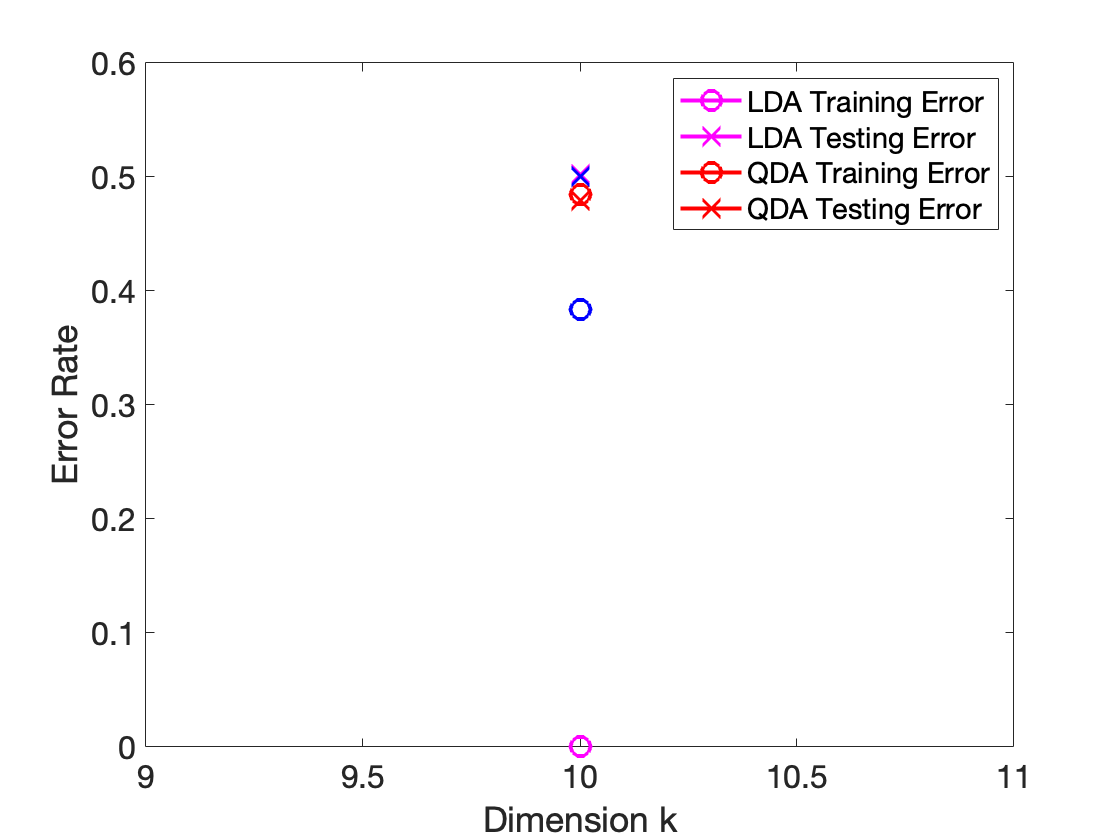


%Plot average training and testing error rates for LDA and QDA.
figure(1)
hold off
plot(kvalues,mean(train_error_NN),'mo-','linewidth',2,'MarkerSize',10)
hold on
plot(kvalues,mean(test_error_NN),'mx-','linewidth',2,'MarkerSize',10)


plot(kvalues,mean(train_error_LDA),'ro-','linewidth',2,'MarkerSize',10)
plot(kvalues,mean(test_error_LDA),'rx-','linewidth',2,'MarkerSize',10)
plot(kvalues,mean(train_error_QDA),'bo-','linewidth',2,'MarkerSize',10)
plot(kvalues,mean(test_error_QDA),'bx-','linewidth',2,'MarkerSize',10)
xlabel('Dimension k')
ylabel('Error Rate')
legend('LDA Training Error','LDA Testing Error','QDA Training Error','QDA Testing Error')
set(gca,'FontSize',16)